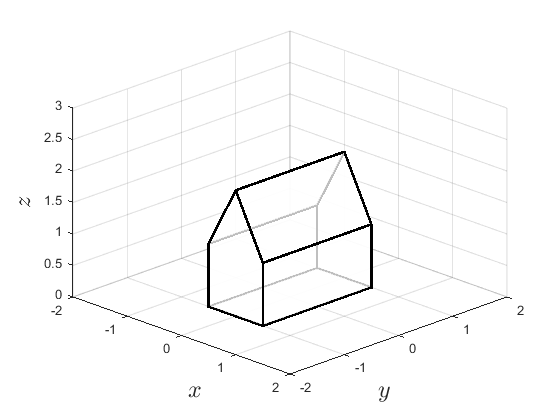

% Define object
V = [-0.5, 0.5, 0.5, -0.5, -0.5, 0.5, 0.5, -0.5, 0, 0 ;
     -1,  -1,   1,    1,   -1,  -1,   1,    1,  -1, 1 ;
      0,   0,   0,    0,    1,   1,   1,    1,   2, 2 ;
      1,   1,   1,    1,    1,   1,   1,    1,   1, 1];

F = [4, 3, 2, 1, 1 ;    % base
     1, 2, 6, 9, 5 ;    % front wall
     2, 3, 7, 6, 6 ;    % right wall
     3, 4, 8, 10, 7 ;   % back wall
     1, 5, 8, 4, 4 ;    % left wall
     6, 7, 10, 9, 9 ;   % right roof
     5, 9, 10, 8, 8 ];  % left roof

% Plot object
patch('Vertices', V(1:3,:)', 'Faces', F, FaceColor='white', FaceAlpha=0.75, LineWidth=2)
xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 18)
ylabel('$y$', 'Interpreter', 'latex', 'FontSize', 18)
zlabel('$z$', 'Interpreter', 'latex', 'FontSize', 18)
view(45, 30)
axis([-2, 2, -2, 2, 0, 3])
grid on

exportgraphics(gcf,'../images/object_space_example.png','Resolution',300) 